## 影像切割(Image Segmentation)

### 閥值運算

即是設定 threshold，將影像轉成黑跟白

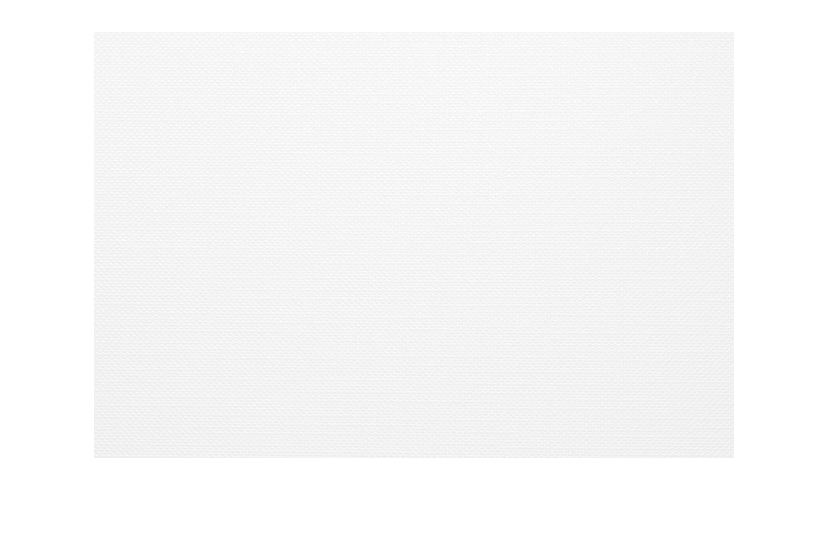

img = imread("Image\handmade.png");
figure; imshow(img);

適當的設定 threshold 可以凸顯出影像的 detail

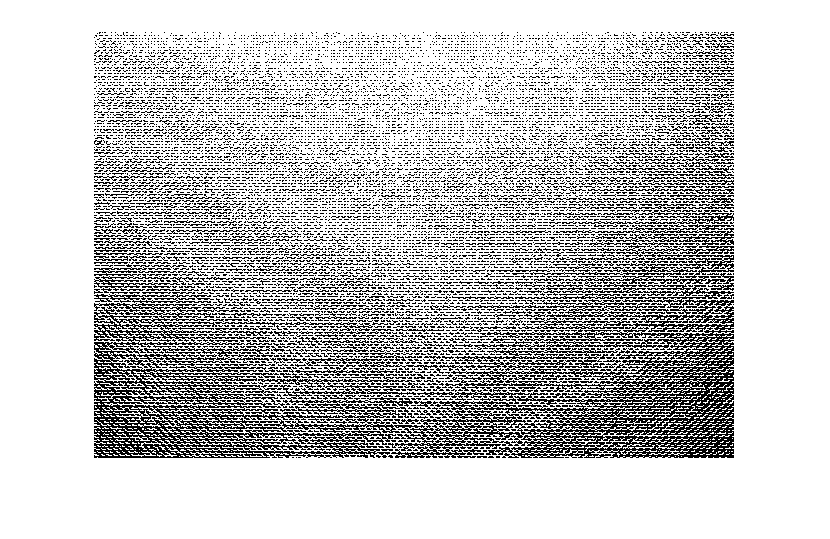

imgn1 = imbinarize(img, 0.95);
figure; imshow(imgn1);

Threshold 的選擇直接影響了效果的好壞，因此 threshold 的選擇極為重要。要選擇一個好的 threshold 可以從他的 histogram 出發，假設我們要將下面這張圖的背景跟物體分離，我們先看看他的 histogram

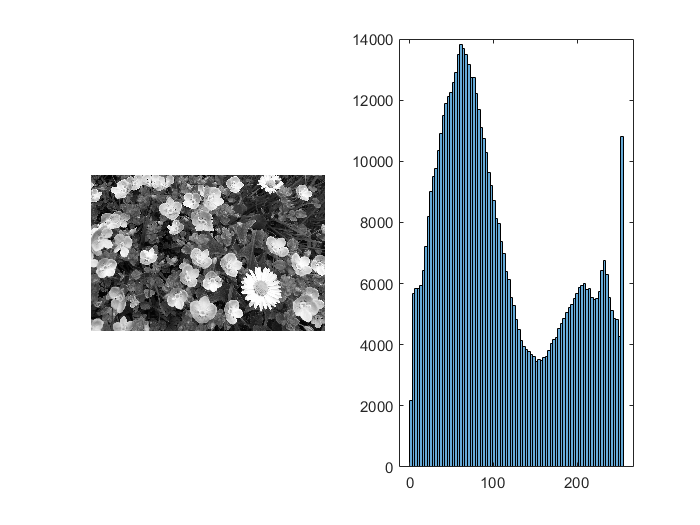

img = imread("Image\daisies.png");
figure;
subplot(121); imshow(img);
subplot(122); histogram(img);

可以看到大約選擇灰階值 150 的位置剛好可以將兩個部分分離

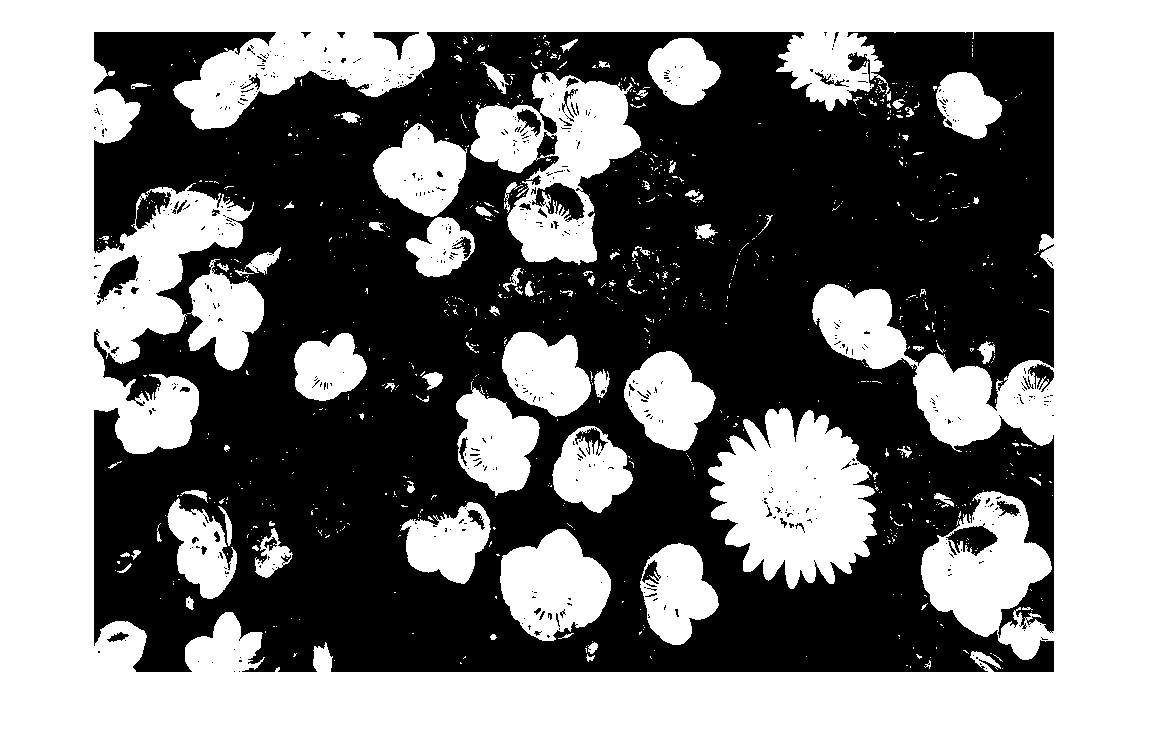

imgn1 = imbinarize(img, 150/255);
figure; imshow(imgn1);

但不是所有的圖片都有這麼漂亮的切點，因此下面有兩種演算法來自動挑選 threshold。

### 大津演算法 (Otsu's Method)

他可以挑選適當的 threshold 使得背景跟物體之間的組間變異數最大化，計算如下，組間變異數的定義為

                                

其中

                                            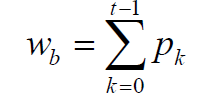

                                                

                                            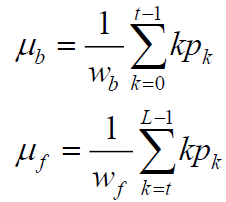

其中 $t$: 選定的 threshold

        $k$: 第 $k$ 階的的灰階值出現的機率

        $L$: 灰階值總數

使用 ***graythresh()*** 可以執行 Otsu's Method

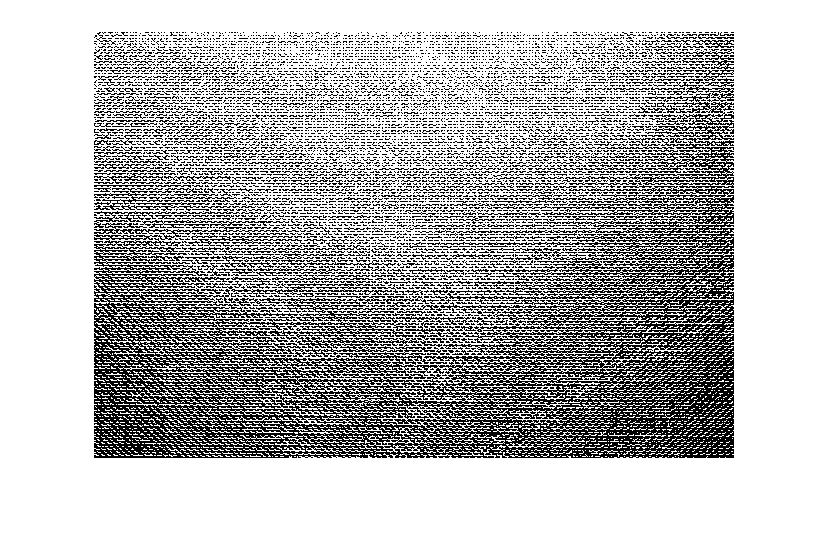

T = graythresh(img);
figure; imshow(imbinarize(img, T))

### ISODATA Algorithm

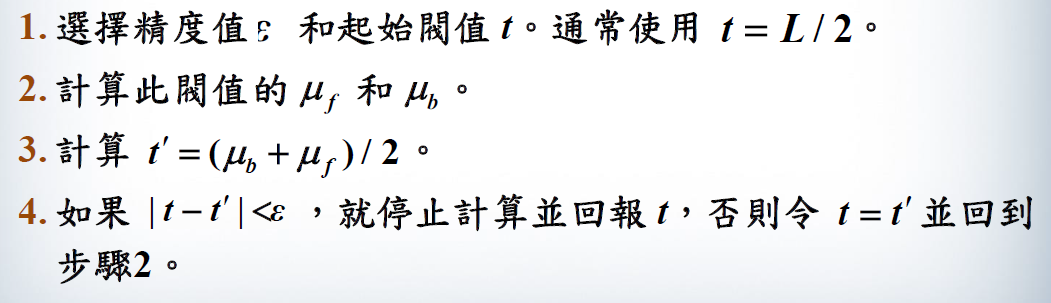

img = imread("Image\cameraman.png");
k = (0:255)';
n = histc(img(:), k); 
p = n/prod(size(img));
wb = cumsum(p);
wf = 1 - wb;
kpc = cumsum(k.*p);
mu_b = kpc./wb;
mu_f = (kpc(end) - kpc) ./ wf;
t = 128;
for i = 1:10
    t1 = floor((mu_b(t) + mu_f(t))/2);
    t = t1;
    t
end

t = 108

t = 95

t = 89

t = 88

t = 88

t = 88

t = 88

t = 88

t = 88

t = 88

## Adaptive Thresholding

有的時候在整張圖片套用一個 threshold 會得到不好的結果，例如影像有漸層

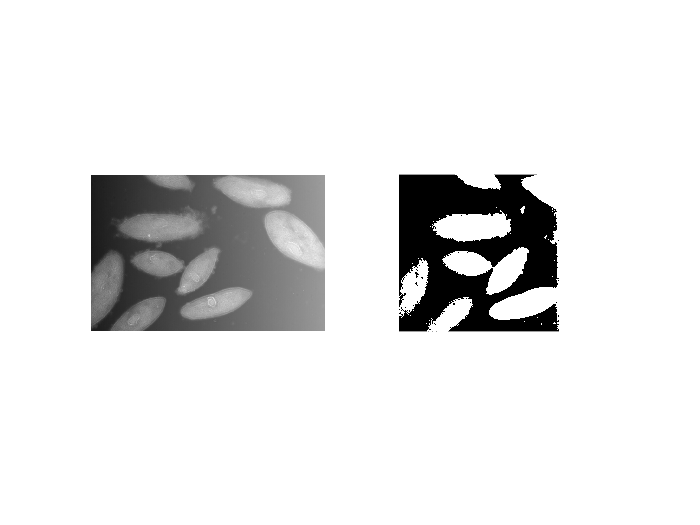

img = im2double(imread("Image\paramecium1.png"));
[r, c] = size(img);
[y, x] = meshgrid(linspace(0,1,c), linspace(0,1,r));
img2 = 1-img+y/2;
T = graythresh(img2);
img3 = imbinarize(img2, T);
figure; 
subplot(121); imshow(img2);
subplot(122); imshow(img3);

可以看到就算用 Otsu's Method，右邊一樣全部不見了。解決的想法就是把圖片切割，再分別做 Threshold Operation

out = zeros(r, c);
starts = 1: c/6: c

starts =      1   163   325   487   649   811


ends = starts(2)-1: c/6: c

ends =    162   324   486   648   810   972


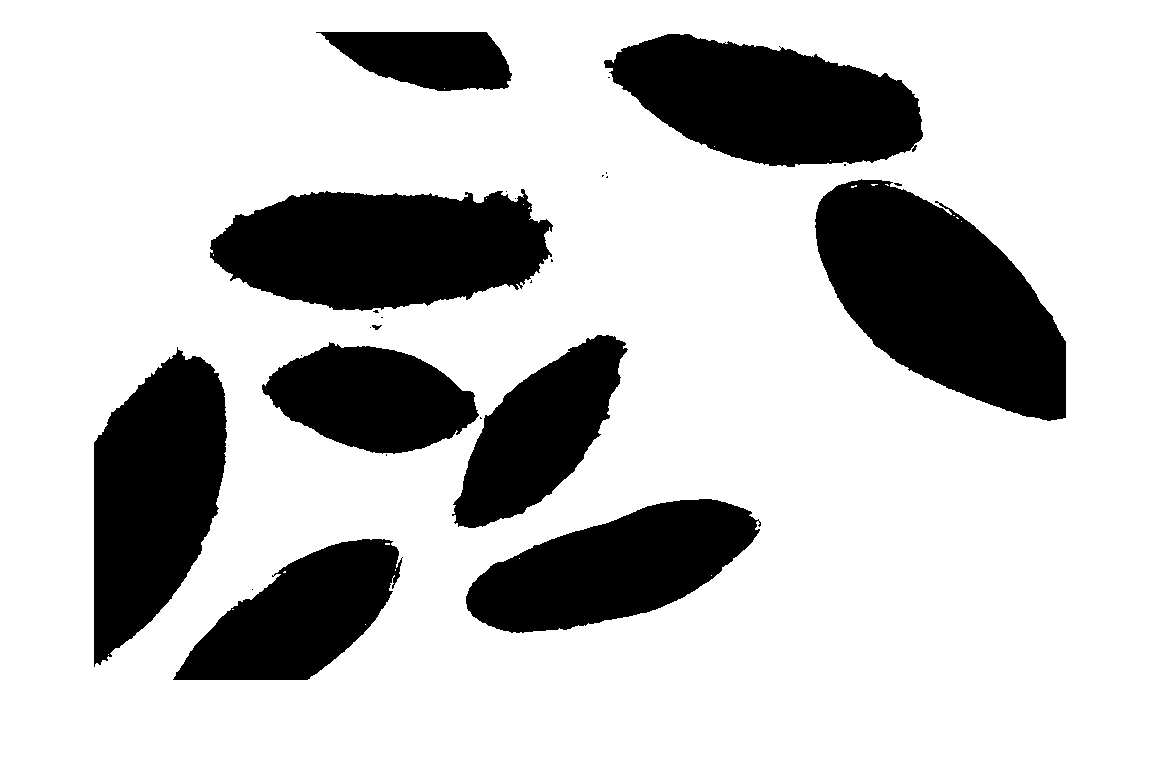

for i = 1:6
    temp = img(:, starts(i):ends(i));
    T = graythresh(temp);
    out(:, starts(i):ends(i)) = imbinarize(temp, T);
end
figure;
imshow(out)

可以看到將其分成直的 6 等分在做 Threshold Operation 效果好很多